I = im2double(imread('4.jpg'));
% I = im2double(imread('synthetic_data/ground_truth/manmade_01.png'));
% i1 = squeeze(I(:,:,1));
I_scale = rescale(I, -0.1, 1.8);

% I = zeros(50,50);
% I(size(I,1)/2,size(I,2)/2)=255;

% LEN = 7;
% THETA = 20;
% PSF = fspecial('disk', 5);
% PSF = fspecial('motion', LEN, THETA)

% PSF2 = fspecial('motion',10,30)
% newPFS2 = zeros(size(PSF1))
% newPFS2(1:size(PSF2,1), 1:size(PSF2,2)) = PSF2

% blury_list = [];
% 
% for len = 20:2:28
%    for theta = 0:10:170
%        PSF1 = fspecial('motion', len, theta);
%        blurred = imfilter(I, PSF1, 'conv', 'circular');
%        blury_list = [blury_list, blurred];
%    end
% end

kernel1 = im2double(imread('synthetic_data/kernel/kernel_01.png'));
z1 = squeeze(kernel1(:,:,1));
z1 = z1/88;

blurred1 = imfilter(I_scale, z1, 'conv', 'symmetric');

%%% Clipping
xMax = 1; xMin = 0;
% Clip to xMax
blurred1(blurred1>xMax) = xMax;
blurred1(blurred1<xMin) = xMin

blurred1 = blurred1(:,:,1) =

    0.0767    0.0762    0.0754    0.0748    0.0750    0.0759    0.0770    0.0776    0.0774    0.0769    0.0765    0.0765    0.0769    0.0774    0.0777    0.0778    0.0776    0.0775    0.0779    0.0785    0.0790    0.0791    0.0789    0.0786    0.0784    0.0780    0.0770    0.0757    0.0749    0.0750    0.0755    0.0762    0.0765    0.0765    0.0764    0.0761    0.0753    0.0747    0.0747    0.0745    0.0741    0.0740    0.0743    0.0747    0.0755    0.0764    0.0767    0.0767    0.0766    0.0766    0.0766    0.0767    0.0769    0.0775    0.0779    0.0779    0.0775    0.0774    0.0776    0.0776    0.0774    0.0773    0.0773    0.0775    0.0774    0.0771    0.0767    0.0762    0.0760    0.0762    0.0766    0.0771    0.0768    0.0756    0.0748    0.0754    0.0767    0.0777    0.0784    0.0777    0.0763    0.0757    0.0761    0.0769    0.0770    0.0766    0.0764    0.0769    0.0777    0.0783    0.0780    0.0766    0.0747    0.0737    0.0740    0.0748    0.0757

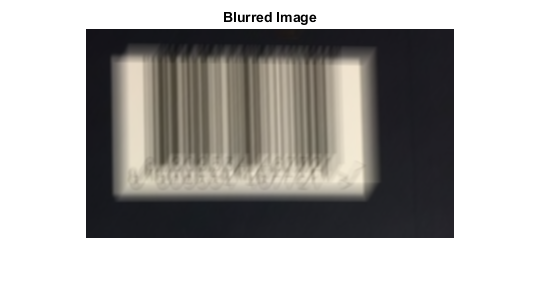


%%% Add noise
% O = imnoise(blurred1,'gaussian')

% blurred1_scaled = blurred1*256*256;
% blurred1_scaled = int16(blurred1_scaled);
% Nr = normalize(blurred1,'range')
% blurred = imfilter(I, blurred1, 'conv', 'circular');

% G = im2double(imread('synthetic_data/uniform/manmade_01_kernel_01.png'))
imshow(blurred1);
title('Blurred Image');